# Tunnel Characterization - Pitot Probe

% If a calibration is already available, load in the calibration variables
% instead of creating a new one

pitot_cal_P = KCal_pressures; % Para Scientific readout (kPa)

pitot_cal_V = KCal_points; % Voltage readout (V or mv)


% If a calibration is already available, load in the calibration variables
% instead of creating a new one

% Use best fit techniques to create calibration curve from collected data

% PitotCal_1 = table2array(PitotCal_1);
% PitotCal_2 = table2array(PitotCal_2);
% PitotCal_3 = table2array(PitotCal_3);
% PitotCal_4 = table2array(PitotCal_4);
% PitotCal_5 = table2array(PitotCal_5);
% PitotCal_6 = table2array(PitotCal_6);
% 
% Pitot_1 = table2array(Pitot_Run1);
% Pitot_2 = table2array(Pitot_Run2);
% Pitot_3 = table2array(Pitot_Run3);
% Pitot_4 = table2array(Pitot_Run4);
% Pitot_5 = table2array(Pitot_Run5);
% Pitot_6 = table2array(Pitot_Run6);
% Pitot_7 = table2array(Pitot_Run7);
% Pitot_8 = table2array(Pitot_Run8);
% Pitot_9 = table2array(Pitot_Run9);
% Pitot_10 = table2array(Pitot_Run10);
% Pitot_11 = table2array(Pitot_Run11);
% Pitot_12 = table2array(Pitot_Run12);
% Pitot_13 = table2array(Pitot_Run13);
% Pitot_14 = table2array(Pitot_Run14);



% Take drvier tube calibration from Campaign 1 or 3 analysis

% DCal1 = table2array(DCal1);
% DCal2 = table2array(DCal2);
% DCal3 = table2array(DCal3);
% DCal4 = table2array(DCal4);
% DCal5 = table2array(DCal5);
% 
% DT_1 = table2array(PitotDT_Run1);
% DT_2 = table2array(PitotDT_Run2);
% DT_3 = table2array(PitotDT_Run3);
% DT_4 = table2array(PitotDT_Run4);
% DT_5 = table2array(PitotDT_Run5);
% DT_6 = table2array(PitotDT_Run6);
% DT_7 = table2array(PitotDT_Run7);
% DT_8 = table2array(PitotDT_Run8);
% DT_9 = table2array(PitotDT_Run9);
% DT_10 = table2array(PitotDT_Run10);
% DT_11 = table2array(PitotDT_Run11);
% DT_12 = table2array(PitotDT_Run12);
% DT_13 = table2array(PitotDT_Run13);
% DT_14 = table2array(PitotDT_Run14);


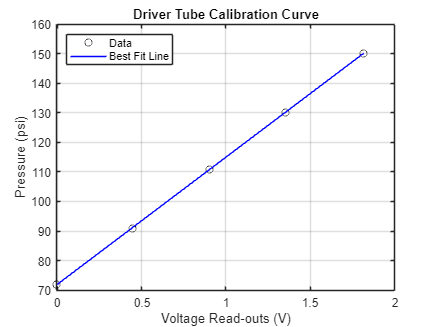

% If a calibration is already available, load in the calibration variables
% instead of creating a new one

% This section plots Driver tube and Kulite calibration curves as well as
% calculates the calibration coefficients needed in later sections

% DCal data

% DCal_points = ; % This is where you can load in another calibration
% DCal_pressures = ;

% DCal_points = [sum(DCal1)./(height(DCal1)), sum(DCal2)./(height(DCal2)), sum(DCal3)./(height(DCal3)), sum(DCal4)./(height(DCal4)), sum(DCal5)./(height(DCal5))];
% DCal_pressures = [71.9 91.0 110.8 130.1 150.2];

% Calibration Curve
DCal_fit_coeffs = polyfit(DCal_pressures, DCal_points, 1);
DCal_fit = polyval(DCal_fit_coeffs, DCal_pressures);

% Plot DCal data and best-fit line
figure;
plot(DCal_points, DCal_pressures, 'ko', 'DisplayName', 'Data');
hold on
plot(DCal_fit, DCal_pressures, 'b-', 'DisplayName', 'Best Fit Line');
grid on
legend('Location', 'northwest')
ylabel('Pressure (psi)');
xlabel('Voltage Read-outs (V)');
title('Driver Tube Calibration Curve');
hold off

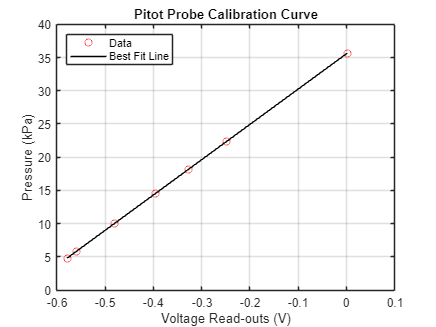

% Create mean vectors

%PitotCal = [mean(PitotCal_1) mean(PitotCal_2) mean(PitotCal_3) mean(PitotCal_4) mean(PitotCal_5) mean(PitotCal_6)];

% Find best-fit line for KCal data

PitotCal_fit_coeffs = KCal_fit_coeffs; % This is where you can load in another calibration
PitotCal_fit = KCal_fit;

% PitotCal_fit_coeffs = polyfit(pitot_cal_P, PitotCal, 1);
% PitotCal_fit = polyval(PitotCal_fit_coeffs, pitot_cal_P);

% Plot KCal data and best-fit line
figure;
plot(pitot_cal_V, pitot_cal_P,'ro', 'DisplayName', 'Data');
hold on
plot(PitotCal_fit, pitot_cal_P, 'k-', 'DisplayName', 'Best Fit Line');
grid on
legend('Location', 'northwest')
ylabel('Pressure (kPa)');
xlabel('Voltage Read-outs (V)');
title('Pitot Probe Calibration Curve');
hold off

% Convert voltage traces to pressure traces (kPa)

Press_Pitot1 = (Pitot_1 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot2 = (Pitot_2 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot3 = (Pitot_3 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot4 = (Pitot_4 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot5 = (Pitot_5 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot6 = (Pitot_6 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot7 = (Pitot_7 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot8 = (Pitot_8 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot9 = (Pitot_9 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot10 = (Pitot_10 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot11 = (Pitot_11 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot12 = (Pitot_12 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot13 = (Pitot_13 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot14 = (Pitot_14 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);



Press_Pitot_DT1 = (DT_1 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_Pitot_DT2 = (DT_2 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_Pitot_DT3 = (DT_3 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_Pitot_DT4 = (DT_4 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_Pitot_DT5 = (DT_5 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_Pitot_DT6 = (DT_6 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_Pitot_DT7 = (DT_7 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_Pitot_DT8 = (DT_8 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_Pitot_DT9 = (DT_9 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_Pitot_DT10 = (DT_10 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_Pitot_DT11 = (DT_11 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_Pitot_DT12 = (DT_12 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_Pitot_DT13 = (DT_13 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_Pitot_DT14 = (DT_14 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);

time = linspace(-200,2000,550001); % time vector starting 200 ms before trigger


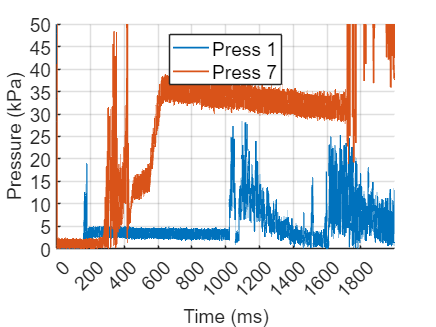

% Plot Pressure Trace
figure;
hold on

plot(time, Press_Pitot1, 'DisplayName', 'Press 1');
% plot(time, Press_Pitot2, 'DisplayName', 'Press 2');
% plot(time, Press_Pitot3, 'DisplayName', 'Press 3');
% plot(time, Press_Pitot4, 'DisplayName', 'Press 4');
% plot(time, Press_Pitot5, 'DisplayName', 'Press 5');
% plot(time, Press_Pitot6, 'DisplayName', 'Press 6');
plot(time, Press_Pitot7, 'DisplayName', 'Press 7');
% plot(time, Press_Pitot8, 'DisplayName', 'Press 8');
% plot(time, Press_Pitot9, 'DisplayName', 'Press 9');
% plot(time, Press_Pitot10, 'DisplayName', 'Press 10');
% plot(time, Press_Pitot11, 'DisplayName', 'Press 11');
% plot(time, Press_Pitot12, 'DisplayName', 'Press 12');
% plot(time, Press_Pitot13, 'DisplayName', 'Press 13');
% plot(time, Press_Pitot14, 'DisplayName', 'Press 14');


grid on

% Adding labels and legend

time_xlabel = 1.79; % Time in seconds displayed on x-axis of plot up to 1.79 sec

% time_xlabel + 0.2 + 0.0001

fsize = 16;
xlim([time(250000 * (0 + 0.2)) time(250000 * (2.0 + 0.2))]); ...
    % time(250000 * time elapsed(sec)), dont forget 200 ms trigger
ylim([0 50]); % kPa
set(gca,'XTick',(-200:200:2000))
set(gca,'YTick',(0:5:200))
ax=gca;
ax.XAxis.FontSize = fsize;
ax.YAxis.FontSize = fsize;
h = findobj(gca,'Type','line');
set(h,'LineWidth',1.5);
%title('Campaign #1 Pressure Traces',FontSize=fsize);
xlabel('Time (ms)',FontSize=fsize);
ylabel('Pressure (kPa)',FontSize=fsize);
legend('Location', 'north','Fontsize', fsize);
grid on

hold off;

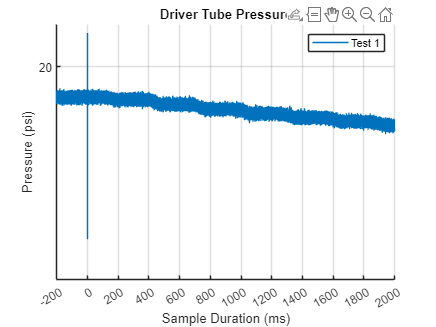

% Plot Driver Tube Pressure

figure;
hold on

plot(time, Press_Pitot_DT1, 'DisplayName', 'Test 1');
% plot(time, Press_Pitot_DT2, 'DisplayName', 'Test 2');
% plot(time, Press_Pitot_DT3, 'DisplayName', 'Test 3');
% plot(time, Press_Pitot_DT4, 'DisplayName', 'Test 4');
% plot(time, Press_Pitot_DT5, 'DisplayName', 'Test 5');
% plot(time, Press_Pitot_DT6, 'DisplayName', 'Test 6');
% plot(time, Press_Pitot_DT7, 'DisplayName', 'Test 7');
% plot(time, Press_Pitot_DT8, 'DisplayName', 'Test 8');
% plot(time, Press_Pitot_DT9, 'DisplayName', 'Test 9');
% plot(time, Press_Pitot_DT10, 'DisplayName', 'Test 10');
% plot(time, Press_Pitot_DT11, 'DisplayName', 'Test 11');
% plot(time, Press_Pitot_DT12, 'DisplayName', 'Test 12');
% plot(time, Press_Pitot_DT13, 'DisplayName', 'Test 13');
% plot(time, Press_Pitot_DT14, 'DisplayName', 'Test 14');

% Adding labels and legend

time_xlabel = 1.79; % Time in seconds displayed on x-axis of plot up to 1.79 sec

% Adding labels and legend
xlim([time(1) time(end)]);
%ylim([10 160])
set(gca,'XTick',(-200:200:2000))
set(gca,'YTick',(20:10:160))
title('Driver Tube Pressure');
xlabel('Sample Duration (ms)');
ylabel('Pressure (psi)');
grid on
legend('show');

hold off;

% Create stagnation pressure ratio arrays

Po2_Po1_Run1 = Press_Pitot1 ./ (6.89476 * Press_Pitot_DT1);
Po2_Po1_Run2 = Press_Pitot2 ./ (6.89476 * Press_Pitot_DT2);
Po2_Po1_Run3 = Press_Pitot3 ./ (6.89476 * Press_Pitot_DT3);
Po2_Po1_Run4 = Press_Pitot4 ./ (6.89476 * Press_Pitot_DT4);
Po2_Po1_Run5 = Press_Pitot5 ./ (6.89476 * Press_Pitot_DT5);
Po2_Po1_Run6 = Press_Pitot6 ./ (6.89476 * Press_Pitot_DT6);
Po2_Po1_Run7 = Press_Pitot7 ./ (6.89476 * Press_Pitot_DT7);
Po2_Po1_Run8 = Press_Pitot8 ./ (6.89476 * Press_Pitot_DT8);
Po2_Po1_Run9 = Press_Pitot9 ./ (6.89476 * Press_Pitot_DT9);
Po2_Po1_Run10 = Press_Pitot10 ./ (6.89476 * Press_Pitot_DT10);
Po2_Po1_Run11 = Press_Pitot11 ./ (6.89476 * Press_Pitot_DT11);
Po2_Po1_Run12 = Press_Pitot12 ./ (6.89476 * Press_Pitot_DT12);
Po2_Po1_Run13 = Press_Pitot13 ./ (6.89476 * Press_Pitot_DT13);
Po2_Po1_Run14 = Press_Pitot14 ./ (6.89476 * Press_Pitot_DT14);

% Plot stagantion pressure ratio traces

 figure;
 hold on 

 % plot(time, Po2_Po1_Run1, 'DisplayName', 'Test 1');
 % plot(time, Po2_Po1_Run2, 'DisplayName', 'Test 2');
 % plot(time, Po2_Po1_Run3, 'DisplayName', 'Test 3');
 % plot(time, Po2_Po1_Run4, 'DisplayName', 'Test 4');
 % plot(time, Po2_Po1_Run5, 'DisplayName', 'Test 5');
 % plot(time, Po2_Po1_Run6, 'DisplayName', 'Test 6');
 % plot(time, Po2_Po1_Run14, 'DisplayName', 'Test 14'); 

 plot(time, Po2_Po1_Run7, 'DisplayName', 'Test 7');   % Isolator Ring Retracted
 plot(time, Po2_Po1_Run8, 'DisplayName', 'Test 8');   % Isolator Ring Retracted
 plot(time, Po2_Po1_Run9, 'DisplayName', 'Test 9');   % Isolator Ring Retracted
 plot(time, Po2_Po1_Run10, 'DisplayName', 'Test 10'); % Isolator Ring Retracted
 plot(time, Po2_Po1_Run11, 'DisplayName', 'Test 11'); % Isolator Ring Retracted
 plot(time, Po2_Po1_Run12, 'DisplayName', 'Test 12'); % Isolator Ring Retracted
 plot(time, Po2_Po1_Run13, 'DisplayName', 'Test 13'); % Isolator Ring Retracted

 % Adding labels and legend

time_xlabel = 1.79; % Time in seconds displayed on x-axis of plot up to 1.79 sec

% time_xlabel + 0.2 + 0.0001

fsize = 16;
xlim([time(250000 * (0 + 0.2)) time(250000 * (2.0 + 0.2))]); ...
    % time(250000 * time elapsed(sec)), dont forget 200 ms trigger
ylim([0 0.1]); % kPa
set(gca,'XTick',(-200:200:2000))
set(gca,'YTick',(0:0.02:0.1))
ax=gca;
ax.XAxis.FontSize = fsize;
ax.YAxis.FontSize = fsize;
h = findobj(gca,'Type','line');
set(h,'LineWidth',1.5);
%title('Campaign #1 Pressure Traces',FontSize=fsize);
xlabel('Time (ms)',FontSize=fsize);
ylabel('Stagnation Pressure Ratio',FontSize=fsize);
legend('Location', 'north','Fontsize', fsize);
grid on

hold off;

% Determine Tunnel noise via pressure trace deviation from mean

% NOTE: For Tstart, use the "humps" in driver tube traces to find clean SS times 
% NOTE: This doesn't take into account the cavity resonance of the kulite, but is a common comparison point to other tunnels

Tstart = 0.25; % time elapsed where steady state driver tube "hump" occurs (sec)
Tend = Tstart + 0.1; % 0.05 seconds after Tstart for clean data pull (sec)

startindex = (250000 * (Tstart + 0.2));
endindex = (250000 * (Tend + 0.2));

Run = Press_Pitot1;

p = polyfit(time(startindex:endindex), Run(startindex:endindex), 1);

smalltime = time(startindex:endindex);

firstfit = polyval(p,smalltime);

pressmeanremove = Run((250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))) - firstfit';

%Pressmean = mean(Run([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))])); % (kPa)

deviation = std(Run((250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2)))); % (kPa)

%Meanremoved = Run - Pressmean;

rootms_withmean = rms(Run((250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))), 1); % (kPa)

rootms_removed = rms(pressmeanremove, 1); % (kPa)

noise_mean = 100 * mean((rootms_removed ./ firstfit)) % Percent noise level

noise_mean = 9.1457


% NOTE: This doesn't take into account the cavity resonance of the kulite

% RMS and Mean Noise levels
               
                  % DT (psi)    Vac (kPa)   

% noise1 = 2.86%       151.2       1.7              
% noise2 = 2.77%       149.5       1.7
% noise3 = 2.81%       120.4       1.16
% noise4 = 3.08%       91.0        0.55
% noise5 = 3.28%       70.9        0.67
% noise6 = 3.69%       50.8        0.53
% noise7 = 4.31%       30.3        0.37


## PSD Calc

figure

hold on
fsamp = 250*10^3;
pointsperblock = 1000;
smoothened = 0;

% Tstart = 0.55; % time elapsed where steady state driver tube "hump" occurs (sec)
% Tend = Tstart + 0.05; % 0.05 seconds after Tstart for clean data pull (sec)

% Run = Press_KRun46;

Pressmean = mean(Run((250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2)))); % (kPa)
noMean = Run((250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2)))-Pressmean;

[Sxx_mean,LLL] = PSD(pressmeanremove,fsamp,pointsperblock,smoothened);
StanDev = sqrt(trapz(LLL(1:200),Sxx_mean(1:200)));

(StanDev/Pressmean)*100

ans = 4.5209

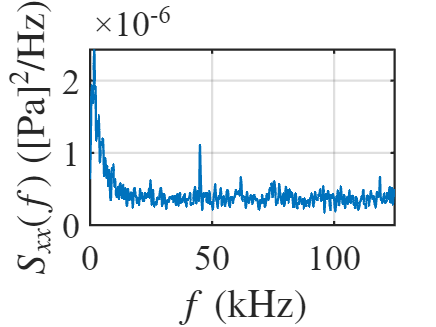


hold off


% PSD Noise levels
               
                  % DT (psi)    Vac (kPa)   

% noise1 = 1.56%       151.2       1.7              
% noise2 = 1.55%       149.5       1.7
% noise3 = 1.61%       120.4       1.16
% noise4 = 1.91%       91.0        0.55
% noise5 = 2.11%       70.9        0.67
% noise6 = 2.29%       50.8        0.53
% noise7 = 2.55%       30.3        0.37

% Po2_mean_array = [26.45 26.77 22.17 15.8 12.27 8.6 5.9]; % kPa

% Average Mach number calculation

Tstart = 0.75; % time elapsed where steady state begins (sec)
Tend = 1.3; % time elapsed where steady state ends (sec)

% Mach number during steady-state run time 

% Find Mean of steady-state run time stagnation pressure, Po2 just passed Normal Shock

Po2 = mean(Press_Pitot7([(250000 * (Tstart + 0.2)) (250000 * (Tend + 0.2))])) % (kPa)

Po2 = 34.3589


% Find Mean of corresponding Driver Tube pressure, Po1, convert to kPa

Po1 = 6.89476 * mean(Press_Pitot_DT7([(250000 * (Tstart + 0.2)) (250000 * (Tend + 0.2))])) % (kPa)

Po1 = 973.6981


% Find Po2 / Po1

Avg_Po2_Po1 = Po2 / Po1

Avg_Po2_Po1 = 0.0353


% Solve for Upstream Mach Number using Po2/Po1 via Normal Shock Relations
% Note: simplified for gamma = 1.4

NormalShockRelation = @(M) ((2.4 * M^2) / (0.4 * M^2 + 2))^3.5 * ...
    (2.4 / (2.8 * M^2 - 0.4))^2.5 - Avg_Po2_Po1;

Avg_Minf = fzero(NormalShockRelation, [1,7]) % [1,7] being the range of guesses

Avg_Minf = 5.7527